# Algoritmo de Enjambre

# Particle Swarm Optimization (PSO) Mejorado

**Profesor:** PhD. Marlon Moscoso Martínez

%% Limpieza del entorno
clc; clear; close all;

%% Definición de la función objetivo
% Para dos variables: f(x,y) = sin(2*x) + cos(y).
f = @(X) sin(2*X(:,1)) + cos(X(:,2));

% Límites del problema en cada dimensión
xMin = -pi; 
xMax =  pi;

%% Parámetros del PSO
npar = 100;    % Número de partículas
maxIter = 50;  % Número máximo de iteraciones

% Coeficientes de aceleración
c1 = 2;  
c2 = 2;

% Peso de inercia máximo y mínimo
wMax = 0.9; 
wMin = 0.4;

% Límite máximo de velocidad para evitar "explosiones" del enjambre
vMax = 0.5*(xMax - xMin);

%% Inicialización aleatoria de partículas y velocidades
% Posiciones iniciales (npar x 2) en el rango [xMin, xMax]
X = xMin + rand(npar,2)*(xMax - xMin);

% Velocidades iniciales (npar x 2) en el rango [-vMax, vMax]
V = -vMax + rand(npar,2)*(2*vMax);

%% Evaluación inicial y configuración de óptimos
fitParticles = f(X);    % Valor de la función por cada partícula
Xopt = X;               % Mejor posición individual
fitOpt = fitParticles;  % Mejor aptitud individual

% Mejor partícula global y su aptitud
[fitG, idxG] = max(fitOpt);
XoptG = Xopt(idxG,:);

%% Arreglos para seguimiento del mejor valor global
bestFitnessHistory = zeros(maxIter,1);

%% Bucle principal de iteraciones
for it = 1:maxIter
    
    % Cálculo del peso de inercia decreciente
    w = wMax - (wMax - wMin)*(it/maxIter);
    
    % Actualización de la velocidad
    V = w*V + c1*rand(npar,2).*(Xopt - X) + c2*rand(npar,2).*(XoptG - X);
    
    % Clampeo de velocidades
    V(V >  vMax) =  vMax;  
    V(V < -vMax) = -vMax;
    
    % Actualización de la posición
    X = X + V;
    
    % Clampeo de posiciones
    X(X >  xMax) =  xMax;
    X(X <  xMin) =  xMin;
    
    % Evaluación de la función objetivo
    fitNew = f(X);
    
    % Actualización de mejores posiciones individuales
    improved = fitNew > fitOpt;
    Xopt(improved,:) = X(improved,:);
    fitOpt(improved) = fitNew(improved);
    
    % Actualización de la mejor partícula global
    [tmpBest, tmpIdx] = max(fitOpt);
    if tmpBest > fitG
       fitG  = tmpBest;
       XoptG = Xopt(tmpIdx,:);
    end
    
    % Almacenar el mejor valor global de esta iteración
    bestFitnessHistory(it) = fitG;
end

%% Resultados finales
disp('Mejor posición global encontrada (XoptG):')

Mejor posición global encontrada (XoptG):


disp(XoptG)

    0.7853    0.0000



disp('Mejor valor de la función (fitG):')

Mejor valor de la función (fitG):


disp(fitG)

    2.0000



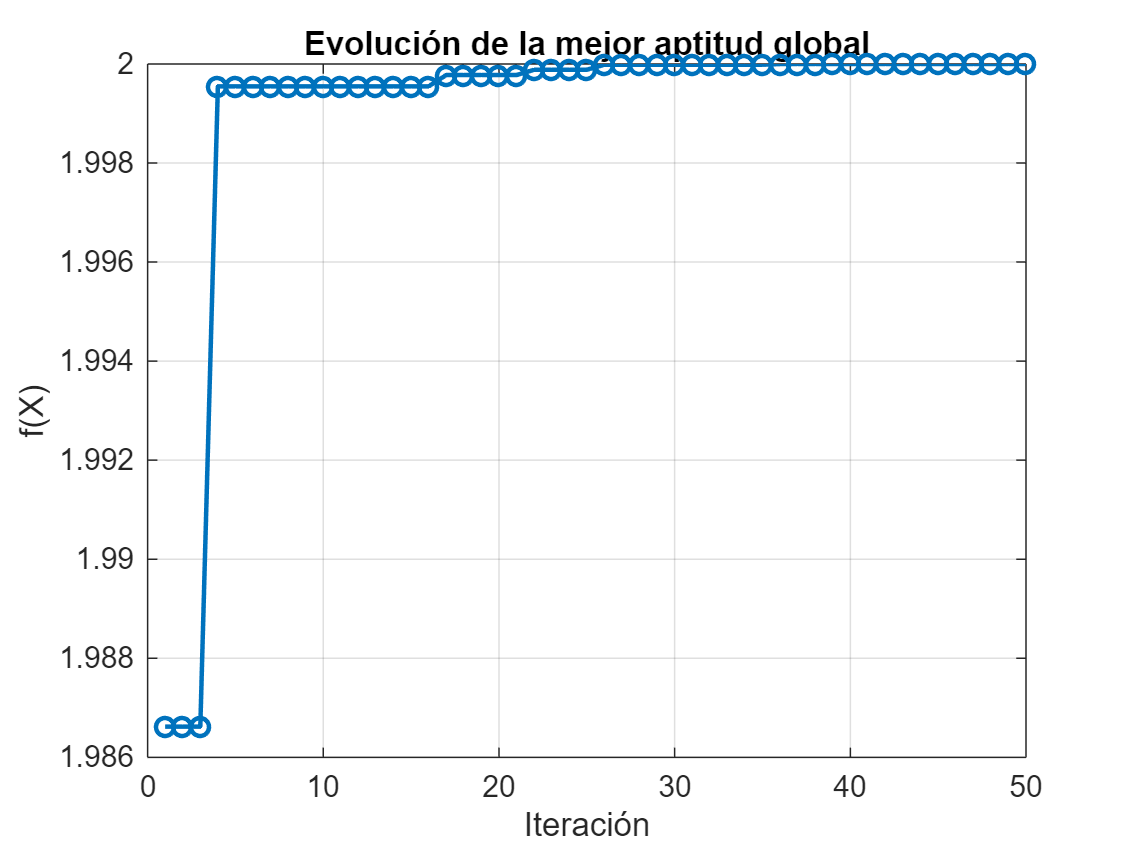


%% Gráfica 1: Evolución del mejor valor global
figure('Name','Evolución del mejor valor global','NumberTitle','off');
plot(1:maxIter, bestFitnessHistory,'-o','LineWidth',1.5);
xlabel('Iteración');
ylabel('f(X)');
title('Evolución de la mejor aptitud global');
grid on;

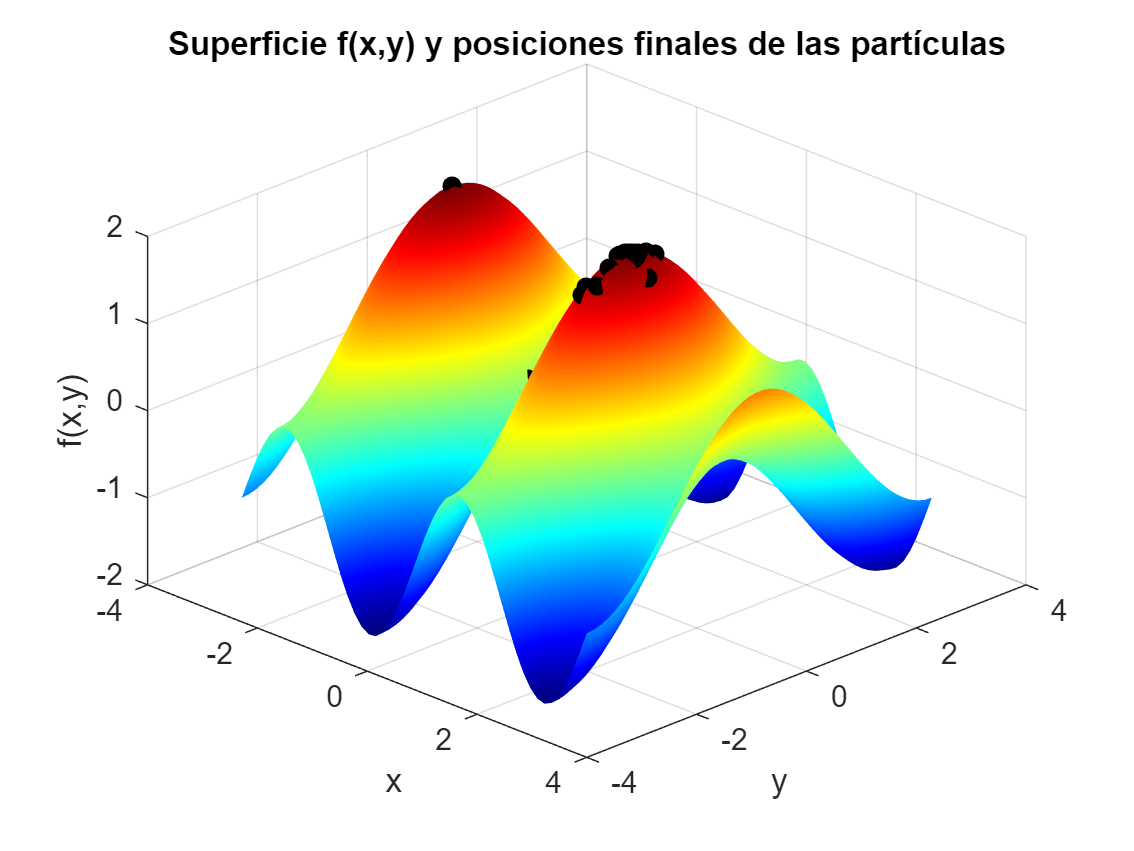


%% Gráfica 2: Distribución final de partículas sobre la superficie
% Crear malla para visualización de la función
npoints = 50;
x_vals = linspace(xMin, xMax, npoints);
y_vals = linspace(xMin, xMax, npoints);
[xx, yy] = meshgrid(x_vals,y_vals);
zz = sin(2*xx) + cos(yy);

figure('Name','Distribución final de partículas','NumberTitle','off');
surf(xx, yy, zz,'EdgeColor','none');
hold on;
colormap jet;
shading interp;
view(45,35);
% Dibujar la posición de las partículas finales
scatter3(X(:,1), X(:,2), f(X), 40, 'k', 'filled');
title('Superficie f(x,y) y posiciones finales de las partículas');
xlabel('x');
ylabel('y');
zlabel('f(x,y)');